usage: homework for week 4

author: 黄哲昊

date: 2020.3.26

%clear all; close all; clc

**个人作业**

**1.  设**$a=1000$**, 取4位有效数字用如下两个等价的式子**


$$x=\sqrt{a+1}-\sqrt{a}, \; x=\frac{1}{\sqrt{a+1}+\sqrt{a}}$$


**   进行计算， 求**$x$**的近似值**$\hat{x}$**， 并将结果与准确值**$x=0.015 807 437\dots$**进行比较， 你的结果各有多少位有效数字？**

解：

$\hat{x_{1}}=\sqrt{a+1}-\sqrt{a}=\sqrt{1001}-\sqrt{1000}=31.64-31.62=0.02$（根据最后的减法保留到小数点后第2位）

$\hat{x_2}=\frac{1}{\sqrt{a+1}+\sqrt{a}}=\frac{1}{\sqrt{1001}+\sqrt{1000}}=\frac{1}{31.64+31.62}=0.01581$（根据最后的除法保留四位有效数字）

根据$x$的近似值$\hat{x}$的相对误差满足$|e_r|\leq\frac{1}{2}\times10^{-p}$，则$\hat{x}$至少有$p$位有效位数，

函数Significant_figures计算相应的有效位数。

format long
a = 1000

a =         1000


x_hat1 = 0.02

x_hat1 =    0.020000000000000


x_hat2 = 0.01581

x_hat2 =    0.015810000000000


x_real = 0.015807437

x_real =    0.015807437000000


x_hat1_sf = Significant_figures(x_hat1, x_real)

x_hat1_sf =      1


x_hat2_sf = Significant_figures(x_hat2, x_real)

x_hat2_sf =      4


因此可知$\hat{x_1}$有1位有效位数，$\hat{x_2}$有4位有效位数。

**2. 序列**$\{y_k\}$**满足递推关系**$y_n=5y_{n-1}-2$**，**$n=1,2,\dots$**. 若取**$y_0=1.73$**计算到**$y_{10}$**时， 将会产生多大的误差?**

解：

$y_0=1.73$为三位有效数字，故结果均保留三位有效数字，得


$$\hat{y_1}=5\times1.73-2=6.65$$



$$\hat{y_2}=5\times6.65-2=33.2-2=31.2$$



$$\hat{y_3}=5\times31.2-2=1.54\times10^2$$



$$\hat{y_4}=5\times154-2=7.68\times10^2$$



$$\hat{y_5}=5\times768-2=3.84\times10^3$$



$$\hat{y_6}=5\times3840-2=19200-2=1.92\times10^4$$



$$\hat{y_7}=5\times19200-2=96000-2=9.60\times10^4$$



$$\hat{y_8}=5\times96000-2=480000-2=4.80\times10^5$$



$$\hat{y_9}=5\times4.80\times10^5-2=2.40\times10^6-2=2.40\times10^6$$



$$\hat{y_{10}}=5\times2.40\times10^6-2=1.20\times10^7-2=1.20\times10^7$$


接下去用递推式计算$y_{10}$的准确值

y_0 = 1.73

y_0 =    1.730000000000000


y_10 = y_0

y_10 =    1.730000000000000


for i = 1:10
    y_10 = 5*y_10 - 2;
end
fprintf("%f", y_10)

12011719.250000

y_hat10 = 1.20e7

y_hat10 =     12000000


e = y_hat10 - y_10

e =     -1.171925000000000e+04


e_r = e / y_10

e_r =     -9.756513415013425e-04


由计算得到$y_{10}=12011719.25$，$e\approx-1.17\times10^4$，$e_r\approx-9.76\times10^{-4}$

**3. 以下是绘制七阶多项式曲线的程序：**

 
$$x=0.988:.0001:1.012;\\
   y=x.^7 - 7*x.^6 + 21*x.^5 - 35*x.^4 + 35*x.^3 - 21*x.^2 + 7*x - 1;$$


**请绘制这条曲线， 讨论其误差来源， 并指出改善的算法。**

解：

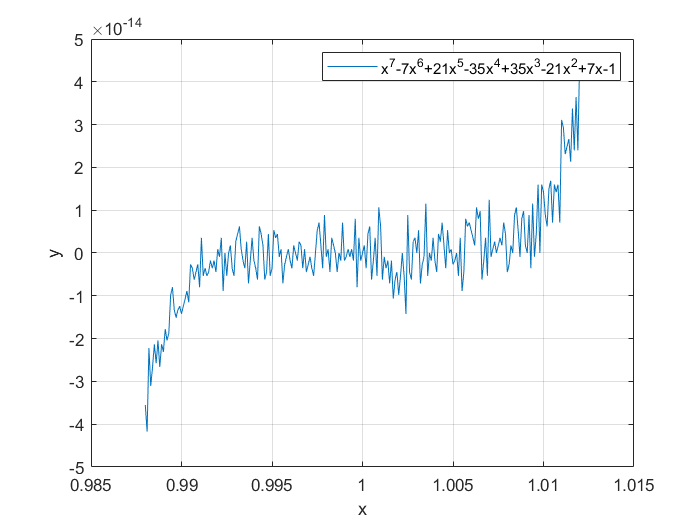

x = 0.988:.0001:1.012;
y = x.^7 - 7*x.^6 + 21*x.^5 - 35*x.^4 + 35*x.^3 - 21*x.^2 + 7*x - 1;
plot(x, y)
grid on
xlabel('x'), ylabel('y')
legend("x^7-7x^6+21x^5-35x^4+35x^3-21x^2+7x-1")

主要误差来源于舍入误差，由于有限的精度运算造成的误差；还有算法误差，由于这种多项式算法执行了$\sum_{i=1}^{7}i=\frac{7\times(7+1)}{2}=28$和7次加法

利用Matlab内置函数：polyval(p,x)可以减少乘法次数，提高精确度

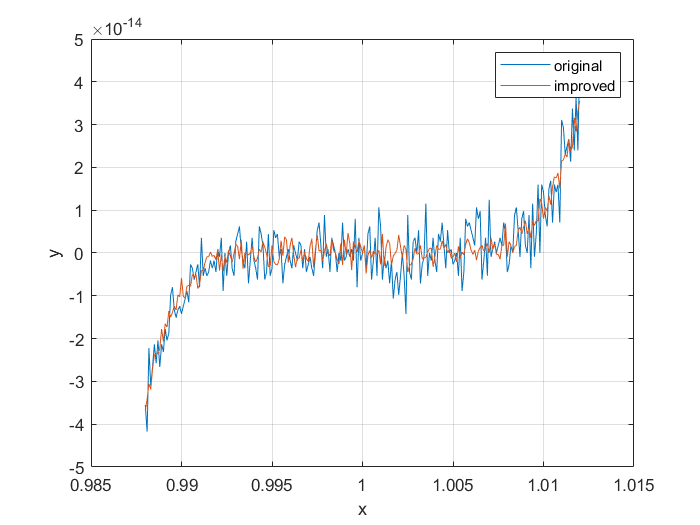

p = [1 -7 21 -35 35 -21 7 -1];
y_improve = polyval(p, x);
plot(x, y, x, y_improve)
grid on
xlabel('x'), ylabel('y')
legend('original', 'improved')

**4. 寻找不严重丢失有效位的方法来计算下列函数**

**a) **$\sqrt{x^2+1}-x$**；**

**b) **$$e^x-x-1$;$**；**

**c) **$$\sin(x)-\tan(x)$$**.**

解：

a) 避免两个相近的数相减：$\frac{1}{\sqrt{x^2+1}+x}$

b)当$x>>0$或$x<<0$时会出现大数吃小数的情况，

为了减小误差：$x(\frac{(e^x-1)}{x}-1)$

c)利用三角恒等式：$sin(1-\frac{1}{cos(x)})$

**5. 函数求值问题的绝对条件数定义为**

  
$$cond=\frac{||问题的解的变化量||}{||输入数据的变化量||}\\=\frac{|f(\hat{x})-f(x)|}{|\hat{x}-x|}$$


**   设 **$$f(x)=\sqrt[3]{x}$$**,**

**   a)  求**$f$**的绝对和相对条件数。**

**   b)  在绝对意义下**$f$**在哪里是良态的？ 在相对意义下呢？**

**   c)  假设用**$$\hat{x}=10^{-16}$$**代替**$$\hat{x}=10^{-17}$$** (一个小的绝对改变，但却是一个大的相对改变)。 利用**$f$**的绝对条件数，请问在自变量这种改变下，**$f$**的改变有多大？**

解：

a）绝对条件数：


$$cond=\frac{|f(\hat{x})-f(x)|}{|\hat{x}-x|}\\f(\hat{x})-f(x)\approx f'(x)(\hat{x}-x)\\\therefore cond=|f'(x)|=|(\sqrt[3]{x})'|=\frac{1}{3\sqrt[3]{x^2}}$$


相对条件数：


$$cond=\left|\frac{[f(\hat{x})-f(x)]/f(x)}{(\hat{x}-x)/x}\right|
\approx \left|\frac{xf'(x)}{f(x)}\right|=\frac{x}{3\sqrt[3]{x^2}\times\sqrt[3]{x}}=\frac{1}{3}$$


b）在绝对意义下，当$x\to0,cond\to\infty$，这时计算$f$是高度敏感的。

在相对意义下，$cond\approx\frac{1}{3}$，计算$f$是非常良态的。

c）当用$\hat{x}=10^{-16}$代替$\hat{x}=10^{-17}$，绝对条件数：$cond=\left|\frac{\sqrt[3]{10^{-16}}-\sqrt[3]{10^{-17}}}{10^{-16}-10^{-17}}\right|=2.7635\times10^{10}$

通过计算可以看到虽然自变量仅仅是一个小的绝对改变，但事实上$f$的改变量相对自变量而言却高出了非常多的数量级。

cond = abs(((10^(-16)).^(1/3)-(10^(-17)).^(1/3))/(10^(-16)-10^(-17)))

cond = 2.7635e+10

计算有效位数的函数:Significant_figures

function output = Significant_figures(x_hat, x_real)
    e_r = (x_hat - x_real) / x_real;
    count = 0;
    while(abs(e_r) <= 0.5*10^(-count))
        count = count + 1;
    end
    output = count;
end